# CircularNetFlow

**Overview**

The `CircularNetFlow` chart creates a circular chart representing the net flow between pairs of categories. There are finitely many categories arranged around the circle. The outer ring of the chart contains circular arcs with size representing the net flow from each category. The inner component of the chart contains nodes with size representing the net flow received by each category. The chart data comprises a table `LinkData`, with the following specifications.

- The table contents `A = LinkData{:, :}` is a square, nonnegative numeric 2-D matrix in which `A(i, j)` contains the (gross) flow from category `i` to category `j`. The number of rows and columns of `A` is equal to the number of categories. The diagonal elements of `A` are all zero, indicating that there is no self-flow from a category to itself.

- The variable names of the table are the names of the categories.

The chart computes the net flow between each pair of categories from the table `LinkData`, before using the net flow data to update the graphics.

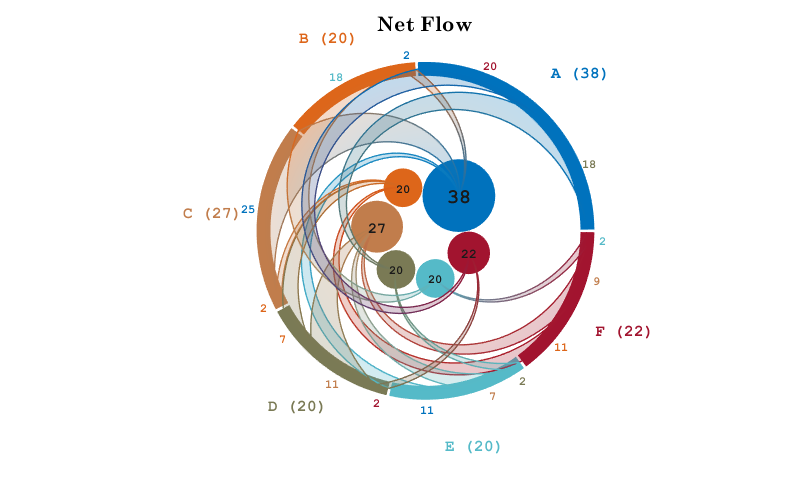

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'CircularNetFlow.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'CircularNetFlow'))) the source code for the `CircularNetFlow` chart.

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.CircularNetFlow

## Create sample chart data.

Each row of the matrix represents a source ("from") category, and each column represents a sink ("to") category. The matrix element `(i, j)` contains the (gross) flow from category `i` to category `j`. The diagonal elements of the matrix are zero, indicating no self-flow.

linkdata = magic(6);
linkdata(1:size(linkdata, 1)+1:end) = 0;

Create a list of text labels, representing the names of the categories.

labels = {'A', 'B', 'C', 'D', 'E', 'F'};

Tabulate the link data.

linkdata = array2table( linkdata, 'VariableNames', labels );

## Create a figure for the chart.

f = galleryFigure( 'Name', 'CircularNetFlow Example' );

## Create the chart, specifying the parent and input data.

CNF = CircularNetFlow( 'Parent', f, ...
                       'LinkData', linkdata );                

## Adjust the chart title.

CNF.Title.Position = [0, 120, 0];

## Display the net flow and net sent/received amounts.

disp( CNF.NetFlow )
disp( 'Net amounts sent:' )
disp( CNF.NetSent )
disp( 'Net amounts received: ' )
disp( CNF.NetReceived )

## Adjust the transparency of the chart.

CNF.FaceAlpha = 0.25;

## Adjust the radial positions of the outer text labels.

CNF.OuterLabelOffset = 40;